# SLCO4A - Aula Prática 2

## Plot com o MATLAB

### Plotando em duas dimensões

a) Plot a função $y\left(x\right)=x^2$, $-2\le x\le 2$

clear all; close all
clc
x0=-2:2
length(x0)
y0=x0.^2;
length(y0)
plot(x0,y0)

**Observação 1:** Note que a representação gráfica correspondeu a uma quantidade de cinco pares ordenados (x,y), que resultou em um gráfico distorcido da representação desejada para a função. Neste tipo de caso deve ser aumentar o número de pontos da variável independente para obter uma melhor representação gráfica.

b) Aumente o número de ponto da variável independente $x$, considerando passo de incremento de $0\ldotp 1$e refaça o item anterior

x=-2:0.1:2
y=x.^2
length(y)
plot(x,y)
plot(y)
y=x.^2;
length(y)


**Observação 2:** Há algumas opções disponíveis no canto superior direito das figuras. As opções permitem  exportar, visualizar valor numérico, dar zoom e editar em janela gráfica externa.  

### Comando `linspace` e `logspace`

 x=0:0.25:1
x=linspace(0,1,5)
%Criar umv etor com cinco pontos espaçados logaritmicamente entre 10^0 até
%10^1
logspace(0,1,5)

### Plotando várias funções em uma figura

c) Plot as seguintes funções em uma mesma figura.$y\left(x\right)=x^2 \cos \left(x\right)$, $g\left(x\right)=\textrm{xcos}\left(x\right)$ e $f\left(x\right)=2^x \textrm{sen}\left(x\right)$, $0\le x\le 2\pi$, considerando 100 pontos.

x=linspace(0,2*pi,100)
y=(x.^2).*cos(x)
g=x.*cos(x)
f=(2.^x).*sin(x)
plot(x,y,x,g,x,f)

**Observação 3:** Note que a figura foi criada com cores predefinidas e linha do tipo sólido. É possível criar gráficos usando cores, símbolos e tipos de linhas personalizados por meio da inserção de outros argumentos na função `plot`, vide opções por meio do comando `help plot.`

### Configurando opções do plot

d) Plot as funções $y_1 \left(x\right)=\textrm{asin}\left(x\right)$e $y_2 \left(x\right)=\textrm{acos}\left(x\right)$, $-1\le x\le 1$ com 15 elementos. Para a primeira função utilize cor preta, linha pontilhada e marcadores do tipo pentagrama. Enquanto que para segunda função utilize cor vermelha, linha tracejada e marcadores do tipo círculo.  

x=linspace(-1,1,15)
y1=asin(x)
y2=acos(x)
plot(x,y1,'k:p',x,y2,'r--o')

Outra forma de sintaxe para o comando `plot` que especifica cor e tipo de linha é da seguinte forma

plot(x,y1,'Color',[1,0,1],'LineWidth',2,"Marker","diamond","Linestyle","-.")

### Comando `hold`

Ao repetir a execução do comando `plot` para uma figura prévia, a representação gráfica obtida anteriormente é descartada. Para manter o gráfico anterior e acrescentar um novo gráfico por meio da repetição do comando `plot` deve-se utilizar o comando `hold on. `Veja o exemplo

x=linspace(0,2*pi,150)
plot(x,cos(x))
hold on
plot(x,sin(x))


### Formatando uma figura

Há alguns comandos úteis para formatação de figuras, tais como: 

`grid-title-xlabel-ylabel-legend-text-gtext-axis-xlim–ylim`


x=linspace(0,2*pi,150)
plot(x,cos(x),'r*',x,sin(x),'k')
legend('cos(x)','sen(x)')
grid
xlabel('Eixo x')
ylabel('Eixo y')
title('Gráfico de cox(x) e sen(x)')
text(3,0.3,'sen(x)')
text(2,0.3,'cos(x)')
axis([2,4,-1,0])

### Plotando em diferentes figuras

Para criar diferentes figuras pode-se especificar a partir do comando `figure(1) ... figure(k) `e utilizar para cada figura o comando `plot.`

Mas também é possível criar múltiplas figuras dentro de uma única figura por meio do comando `subplot(m,n,p). `Com este comando cria-se dentro de uma mesma janela de figura que estará dividida em `mxn` pequenas subfiguras.

e) Utilizando o comando `subplot` plot as seguintes funções $f\left(x\right)=\cos \left(x\right)$, $g\left(x\right)=e^{-\frac{x}{2\pi }} \cos \left(x\right)$, $f\left(x\right)=e^{\frac{x}{2\pi }} \cos \left(x\right)$ em uma única figura contendo 3 subfiguras disposta em um arranjo 3x1

figure
x=0:0.1:4*pi

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


subplot(3,1,1)
plot(x,cos(x))
grid on
subplot(3,1,2)
plot(x, exp(-x/(2*pi)).*cos(x))
grid on
subplot(3,1,3)
plot(x, exp(x/(2*pi)).*cos(x))
grid on

### `Funções por partes`

f) Obtenha a representação gráfica de uma função definida por partes, tal que

t1=-2:0.01:2
t2=2.01:0.01:4.99
t3=5:0.01:8
f1=ones(size(t1))
f2=zeros(size(t2))
f3=t3.*sin(4*pi*t3)
t=[t1 t2 t3]
f=[f1 f2 f3]
figure
plot(t,f)


## `Outros comandos para plotar uma função`

Além do comando `plot `há outros comandos que podem ser empregados para obter uma representação gráfica de uma função, tais como:

`loglog-semilogx-semilogy-area-fplot-ezplot`

f) Considere a função $y\left(x\right)=2x+30$, $1\le x\le 1000$. Obtenha diferentes representações gráficas utilizando outros comandos além do `plot.`

x=1:1000
y=2*x+30
figure
plot(x,y)
figure
loglog(x,y)
figure
semilogy(x,y)
figure
semilogx(x,y)
figure
area(x,y)
figure
fplot(@(x)2.*x+30,[1,1000])
%fplot('2*x+30',[1,1000])
%ezplot('2*x+30',[1,1000])

### Plot de funções de tempo discreto

g) Considere a função de tempo discreto $f\left(k\right)=k^2$, $k\in Z:-3\le k\le \;3$.

k=-3:3;
f=k.^2;
stem (k,f)
stem(k,f,"r*")

### Gráfico em coordenadas polares

theta = linspace(0,4*pi,50)

theta =          0    0.2565    0.5129    0.7694    1.0258    1.2823    1.5387    1.7952    2.0517    2.3081    2.5646    2.8210    3.0775    3.3339    3.5904    3.8468    4.1033    4.3598    4.6162    4.8727    5.1291    5.3856    5.6420    5.8985    6.1550    6.4114    6.6679    6.9243    7.1808    7.4372    7.6937    7.9502    8.2066    8.4631    8.7195    8.9760    9.2324    9.4889    9.7453   10.0018   10.2583   10.5147   10.7712   11.0276   11.2841   11.5405   11.7970   12.0535   12.3099   12.5664


c=theta

c =          0    0.2565    0.5129    0.7694    1.0258    1.2823    1.5387    1.7952    2.0517    2.3081    2.5646    2.8210    3.0775    3.3339    3.5904    3.8468    4.1033    4.3598    4.6162    4.8727    5.1291    5.3856    5.6420    5.8985    6.1550    6.4114    6.6679    6.9243    7.1808    7.4372    7.6937    7.9502    8.2066    8.4631    8.7195    8.9760    9.2324    9.4889    9.7453   10.0018   10.2583   10.5147   10.7712   11.0276   11.2841   11.5405   11.7970   12.0535   12.3099   12.5664


polarplot(theta, c, '--*')

### Gráfico tridimensional

x=0:.1:100

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


y= cos(x)

y =     1.0000    0.9950    0.9801    0.9553    0.9211    0.8776    0.8253    0.7648    0.6967    0.6216    0.5403    0.4536    0.3624    0.2675    0.1700    0.0707   -0.0292   -0.1288   -0.2272   -0.3233   -0.4161   -0.5048   -0.5885   -0.6663   -0.7374   -0.8011   -0.8569   -0.9041   -0.9422   -0.9710   -0.9900   -0.9991   -0.9983   -0.9875   -0.9668   -0.9365   -0.8968   -0.8481   -0.7910   -0.7259   -0.6536   -0.5748   -0.4903   -0.4008   -0.3073   -0.2108   -0.1122   -0.0124    0.0875    0.1865


z= sin(x)

z =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


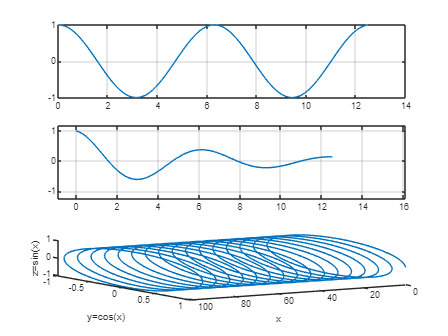

plot3(x,y,z)
xlabel('x')
ylabel('y=cos(x)')
zlabel('z=sin(x)')